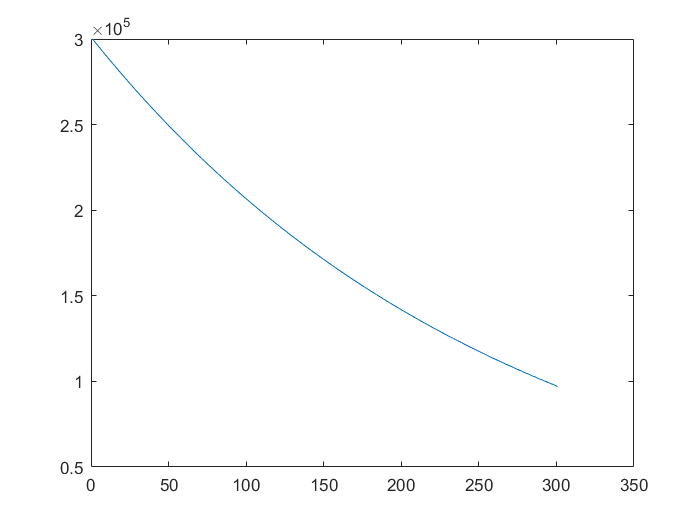

% compressed air engine project.

connecting_rod_length=30/1000; % 30mm
height_of_pistol=12/1000; % connecting point to the rod is in the middle
crank_shaft_r=6/1000;
pistol_r=10/1000;
ball_dia=6/1000;
ball_mass=0.113/1000; % g
pistol_cross_area=pi*pistol_r^2;
volume_of_inlet_air=pistol_cross_area*height_of_pistol;
volume_of_exterior_container=1/1000; % 1L comtainer 
air_pressure=1*10^5;
% the volume of inlet air is a constant. the pressure of it equals 
% to the compressed air. take the inlet and outlet of air as instantaneous

initial_compressed_air_pressure=3*10^5; % 3 air pressure
pressure(1)=initial_compressed_air_pressure;
rounds=300;
for i=1:rounds
    pressure(i+1)=pressure(i)*volume_of_exterior_container...
        /(volume_of_exterior_container+volume_of_inlet_air);
    work_done(i)=(pressure(i)-air_pressure)*volume_of_inlet_air;
    force(i)=(pressure(i)-air_pressure)*pistol_cross_area;
end

%spins=linspace(1,100,101);
plot(1:(rounds+1),pressure)

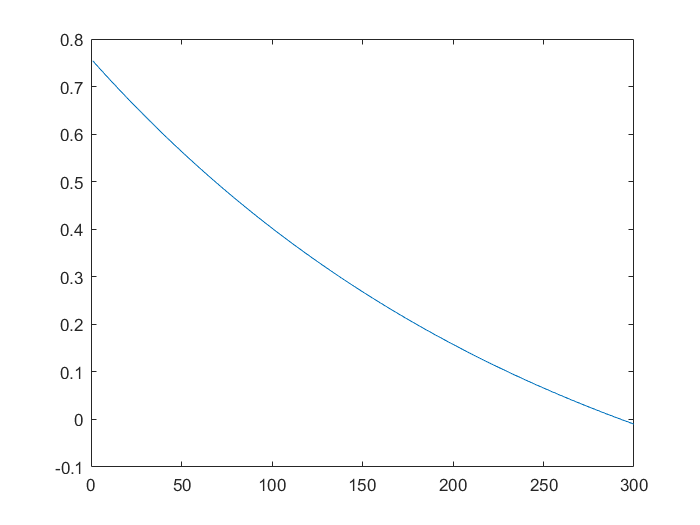

plot(1:rounds,work_done)

total_work=sum(work_done);

total_work = 90.6461